- Figure 4-16 shows a truss structure with two uniform members made of same material. The truss structure is constrained at two ends. The cross-sectional area of all the truss members is 0.01$m^2$, and the Young’s modulus of the material is 2.0E10$\frac{N}{m^2 }$.  Using the finite element method, calculate:

- a) all the nodal displacements; 

- b) the internal forces in all the truss members; and  

- c) the reaction forces at the supports.

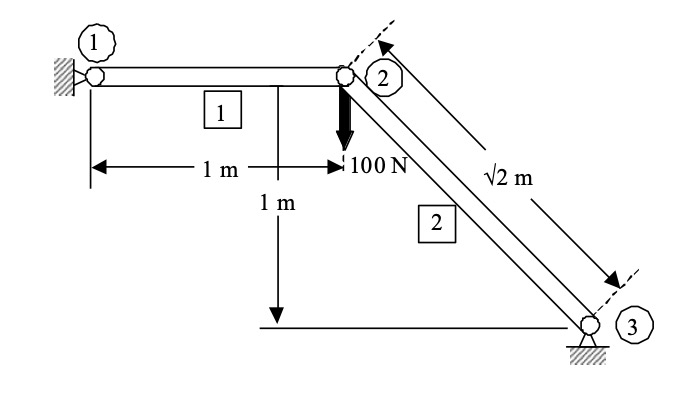

Figure 4-16 A truss element with 2 members

#### a) The nodal displacements

The Dimensions and properties of truss members

The Global coordinates of nodes and direction cosines of elements 

#### Build Element Matrices


$$K_e =T^T k_e T$$



$$K_e =\frac{\textrm{AE}}{l_e }\left\lbrack \begin{array}{cccc}
{l^{2\;} }_{\textrm{ij}}  & l_{\textrm{ij}} m_{\textrm{ij}}  & {{-l}^{2\;} }_{\textrm{ij}}  & -l_{\textrm{ij}} m_{\textrm{ij}} \\
l_{\textrm{ij}} m_{\textrm{ij}}  & {m^{2\;} }_{\textrm{ij}}  & -l_{\textrm{ij}} m_{\textrm{ij}}  & {{-m}^{2\;} }_{\textrm{ij}} \\
{{-l}^{2\;} }_{\textrm{ij}}  & -l_{\textrm{ij}} m_{\textrm{ij}}  & {l^{2\;} }_{\textrm{ij}}  & l_{\textrm{ij}} m_{\textrm{ij}} \\
-l_{\textrm{ij}} m_{\textrm{ij}}  & {{-m}^{2\;} }_{\textrm{ij}}  & l_{\textrm{ij}} m_{\textrm{ij}}  & {m^{2\;} }_{\textrm{ij}} 
\end{array}\right\rbrack$$


% Constants and Parameters
E = 2e10;         % Young's modulus in Pascals [N/m^2]
A = 0.01;         % Cross-sectional area in [m^2]
L = [1, sqrt(2)]; % Length of elements in meters

% Direction cosines for each element
l = [1,         1;  
     -1/sqrt(2), 1/sqrt(2)]; % l_ij for each element

m = [ 0,         0;   
      1/sqrt(2), 1/sqrt(2)]; % m_ij for each element

% Number of elements 
num_elements = 2;

% Initialize global stiffness matrix 
K_global = zeros(3 * num_elements); % Adjust size according to the number of nodes

% Build elemement matrices and assmeble the global stiffness matrix 
for i = 1:num_elements
    % Element stiffness matrix for the ith element
    k_e = (A*E / L(i)) * [     
                            l(i,1)^2,       l(i,1)*m(i,1), -l(i,1)^2,      -l(i,1)*m(i,1);
                            l(i,1)*m(i,1),  m(i,1)^2,      -l(i,1)*m(i,1), -m(i,1)^2;
                           -l(i,1)^2,      -l(i,1)*m(i,1),  l(i,1)^2,       l(i,1)*m(i,1);
                           -l(i,1)*m(i,1), -m(i,1)^2,       l(i,1)*m(i,1),  m(i,1)^2
                           ];

    % Determine the global matrix indices for the local element nodes
    % This will depend on how your nodes are connected in the global structure
    global_indices = [2*i-1, 2*i, 2*i+1, 2*i+2];

    % Assemble the element stiffness matrix into the global matrix
    K_global(global_indices, global_indices) = K_global(global_indices, global_indices) + k_e;
end

disp(K_global); % Global stiffness matrix

   1.0e+08 *

    2.0000         0   -2.0000         0         0         0
         0         0         0         0         0         0
   -2.0000         0    2.7071   -0.7071   -0.7071    0.7071
         0         0   -0.7071    0.7071    0.7071   -0.7071
         0         0   -0.7071    0.7071    0.7071   -0.7071
         0         0    0.7071   -0.7071   -0.7071    0.7071



#### Apply Boundary Conditions

Boundary conditions 


$$D_1 =D_2 =D_5 =D_6 =0$$


constrained_dofs = [1, 2, 5, 6]; % Degrees of Freedom that are constrained

% Modify the global stiffness matrix and the force vector
K_reduced = K_global;
K_reduced(constrained_dofs, :) = [];  % Remove constrained rows
K_reduced(:, constrained_dofs) = [];  % Remove constrained columns
disp(K_reduced); % The reduced stiffness matrix

   1.0e+08 *

    2.7071   -0.7071
   -0.7071    0.7071



The force vector 

% The forces applied to the structure
F_global = zeros(size(K_global, 1), 1);

% A 100 N force is applied in the negative y-direction at node 2
F_global(4) = -100; 
disp(F_global); % The force vector

     0
     0
     0
  -100
     0
     0



Reducing the entries from the force vector that correspond to constrained DOFs

F_reduced = F_global;
F_reduced(constrained_dofs) = [];
disp(F_reduced); % The force vector

     0
  -100



#### Solving the FE matrix equation

We can solve for the displacements from 


$$\textrm{KD}=F\longrightarrow D=\frac{K}{F}$$


To obtain the displacements $D_3$ and $D_4$

D_reduced = K_reduced \ F_reduced;

% Insert the constrained displacements (which are zeros) back into the displacement vector
D_global = zeros(size(K_global, 1), 1);
unconstrained_dofs = setdiff(1:size(K_global, 1), constrained_dofs);
D_global(unconstrained_dofs) = D_reduced;

disp(D_global) % Displacement vector

   1.0e-05 *

         0
         0
   -0.0500
   -0.1914
         0
         0



### Part B - Internal forces in all the truss members 

To obtain the stresses in the truss members we use 


$$\sigma_x =\textrm{EB}d_e =\textrm{EBT}{\mathrm{D}}_{\mathrm{e}}$$


For element 1 we have 


$$\sigma_1 =\textrm{EBT}{\mathrm{D}}_{\mathrm{e}}$$


l_e1 = L(1);
B1   = [-1/l_e1 1/l_e1];
T1   = [
         l(1,1) m(1,1) 0      0; 
         0      0      l(1,2) m(1,2)];
 
remove_1 = [5, 6]; 
D_e1 = D_global;
D_e1(remove_1) = [];
% disp(D_e1); 

sigma_x1 = E * B1 * T1 * D_e1;
disp(sigma_x1); 

  -1.0000e+04



For element 2 we have 


$$\sigma_2 =\textrm{EBT}{\mathrm{D}}_{\mathrm{e}}$$


l_e2 = L(2);
B2   = [-1/l_e2 1/l_e2];
T2   = [
         l(2,1) m(2,1) 0      0; 
         0      0      l(2,2) m(2,2)];
 
remove_2 = [1, 2]; 
D_e2 = D_global;
D_e2(remove_2) = [];
% disp(D_e2);

sigma_x2 = E * B2 * T2 * D_e2;
disp(sigma_x2); 

   1.4142e+04



% % Number of elements 
% num_elements = 2;
% 
% % Initialize global stiffness matrix 
% K_global = zeros(3 * num_elements); % Adjust size according to the number of nodes
% 
% % Build elemement matrices and assmeble the global stiffness matrix 
% for i = 1:num_elements
% 
%     l_e = L(i)
% 
%     B1   = [-1/l_e 1/l_e]
% 
%     T1   = [ l(i,1) m(i,1) 0      0; 
%              0      0      l(i,2) m(i,2)]
% 
%     remove_1 = [5, 6]; 
%     D_e1 = D_global;
%     D_e1(remove_1) = [];
% 
%     k_e = (A*E / L(i)) * [     
%                             l(i,1)^2,       l(i,1)*m(i,1), -l(i,1)^2,      -l(i,1)*m(i,1);
%                             l(i,1)*m(i,1),  m(i,1)^2,      -l(i,1)*m(i,1), -m(i,1)^2;
%                            -l(i,1)^2,      -l(i,1)*m(i,1),  l(i,1)^2,       l(i,1)*m(i,1);
%                            -l(i,1)*m(i,1), -m(i,1)^2,       l(i,1)*m(i,1),  m(i,1)^2
%                            ];
% 
%    
%     global_indices = [2*i-1, 2*i, 2*i+1, 2*i+2];
% 
%     K_global(global_indices, global_indices) = K_global(global_indices, global_indices) + k_e;
% end

We can then obtain the internal forces in the two truss members from the following 


$${F_e =\sigma }_x^e A_e$$


For element 1 we have 


$${F_1 =\sigma }_x^1 A_1$$


F_1 = sigma_x1 * A; % [N]
disp(F_1); 

 -100.0000



For element 2 we have 


$${F_2 =\sigma }_x^2 A_2$$


F_2 = sigma_x2 * A; % [N]
disp(F_2); 

  141.4214



#### Part C - The reaction forces at the supports

We can solve for the reaction forces from the following 


$$\textrm{KD}=F$$


F = K_global * D_global %[N]

F =   100.0000
         0
         0
 -100.0000
 -100.0000
  100.0000
